clear, clc

## DATA

%Student ID 2024161152
A1 = 2;
A2= 5;
L1 = 20+A1/0.5; % Length of the first medium in meters
L2 = 15+A2/0.5; % Length of the second medium in meters
c1 = 1500.0+10.0*A1-A2; % Speed of sound in the first medium in m/s
c2 = (1800.0+20.0*A2*A1)*(1+0.02*1i*(2+sqrt(A1))); % Speed of sound in the second medium in m/s
rho = 1000; % Density in kg/m^3
f = 500.0+A2*20.0+A1; % Excitation frequency in Hz
w = 2 * pi * f; % Angular frequency

% Total length and number of points
L = L1 + L2

L = 49

## Wave number

%k1 = 2*pi*f/c1; 
%k2 = 2*pi*f/c2;
%commenting above as these are already embedeed in the matrices below

## Mesh

dx = 0.505;
ne =round(L/dx) %number of elements

ne = 97


x = 0:dx:L;
n_l = 1:ne;
n_r = 2:ne+1;

## Plotting the discretized length

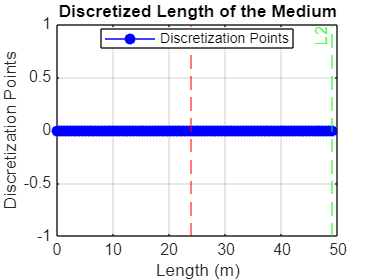

plot(x, zeros(size(x)), 'bo-', 'MarkerFaceColor', 'b'); % Plot points on x-axis
hold on;
title('Discretized Length of the Medium');
xlabel('Length (m)');
ylabel('Discretization Points');
grid on;
ylim([-1 1]); % Set y-limits to visualize points better
xline(L1, 'r--', 'L1', 'LabelHorizontalAlignment', 'left'); % Line for Medium 1
xline(L1 + L2, 'g--', 'L2', 'LabelHorizontalAlignment', 'left'); % Line for Medium 2
legend('Discretization Points', 'Location', 'Best');
hold off;

## system matrices

K = zeros(ne+1);
M = zeros(ne+1);
C = zeros(ne+1);

for ii = 1:ne
    Le = dx;
    ndof = [n_l(ii) n_r(ii)]; % Degrees of freedom for the element
    if x(ii) < L1
        % Fluid M1
        [ke1, me1] = keme(Le, rho, c1);
        K(ndof, ndof) = K(ndof, ndof) + ke1 ;
        M(ndof, ndof) = M(ndof, ndof) + me1;
    elseif x(ii)==L1
        M(n_l(ii),n_l(ii-1))=Le/(6*c1^2*rho);
        M(n_l(ii),n_l(ii))=Le/(3*rho*(1/c1^2+1/c2^2));
        M(n_l(ii),n_l(ii+1))=Le/(6*c2^2*rho);
        K(n_l(ii),n_l(ii-1))=-1/(rho*Le);
        K(n_l(ii),n_l(ii))=2/(rho*Le);
        K(n_l(ii),n_l(ii+1))=-1/(rho*Le);
     elseif x(ii)> L1
        % Fluid M2
        [ke1, me2] = keme(Le, rho, c2);
        K(ndof, ndof) = K(ndof, ndof) + ke1 ;
        M(ndof, ndof) = M(ndof, ndof) + me2;
    end
   
end
%right-hand side
%impedance on the right hand of the system
Z = rho*c2;

C(end,end) = 1/Z;

KK = K+1i*w*C-w^2*M; % K*P+1i*w*C-2^2*M*P

## boundary conditions for leftmost node

%Drichlet conditions on left most node 
F = zeros(ne+1, 1);
KK(1,:) = 0;
KK(1,1) = 1;
F(1) = 1;


## SOLVE!

P = (KK\F);

## Plot Results

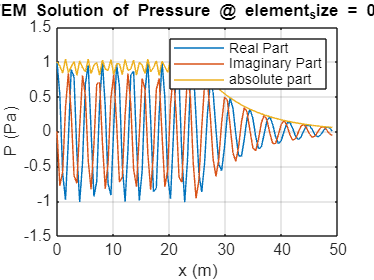

plot(x,real(P), x, imag(P),x, abs(P))
grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real Part', 'Imaginary Part','absolute part');
title('FEM Solution of Pressure @ element_size = 0.5m');

## Analytical solution

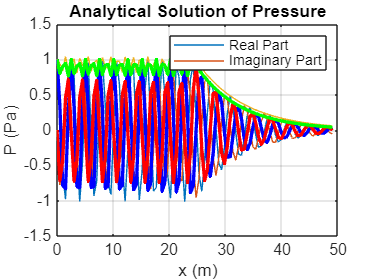

P_analytic = solution_1D(f, c1, c2, L1, L2, x);  % Analytical solution

% Plot the real and imaginary parts of the analytical solution
figure(2);
hold on;
plot(linspace(0, L, ne+1), real(P_analytic), 'b-', 'LineWidth', 2);  % Real part
plot(linspace(0, L, ne+1), imag(P_analytic), 'r-', 'LineWidth', 2);  % Imaginary part
plot(linspace(0, L, ne+1), abs(P_analytic), 'g-', 'LineWidth', 2);  % Absolute part
hold off;

grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real Part', 'Imaginary Part');
title('Analytical Solution of Pressure');

## convergence

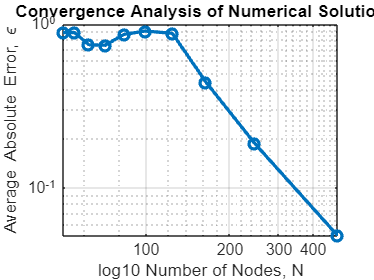

% Define the range of element sizes
num_discretizations = 10;
element_sizes = linspace(1.0, 0.1, num_discretizations); % From 1.0 m to 0.1 m
epsilon = zeros(num_discretizations, 1);
npoints = zeros(num_discretizations, 1);

for n = 1:num_discretizations
    dx = element_sizes(n); % Current element size
    N = round(L / dx); % Number of nodes
    npoints(n) = N; % Store number of nodes

    % Compute FEM solution
    P_FEM = fem_wave_solver(N - 1, L1, L2, c1, c2, rho, f); 

    % Compute analytical solution
    x = linspace(0, L, N); % Nodes for analytical solution
    P_analytical = solution_1D(f, c1, c2, L1, L2, x); 

    % Calculate average absolute error
    epsilon(n) = sum(abs(P_analytical - P_FEM)) / N; 
end

% Ensure epsilon is positive for log scale
epsilon = abs(epsilon); 
% Plotting the convergence curve
figure;
loglog((npoints+1), epsilon, 'o-', 'LineWidth', 2);
grid on;
xlabel('log10 Number of Nodes, N');
ylabel('Average Absolute Error, \epsilon');
title('Convergence Analysis of Numerical Solution');

% Lets visualize the solution with the least error possible
[min_value, min_index] = min(epsilon)

min_value = 0.0508

min_index = 10

element_size_optimal = L/npoints(min_index)

element_size_optimal = 0.1000

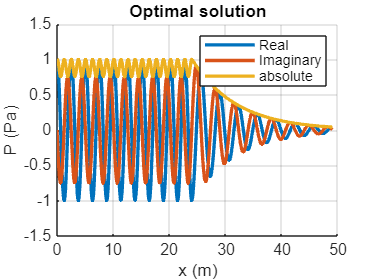

% Use the optimal grid size
P = fem_wave_solver(npoints(min_index)-1, L1, L2, c1, c2, rho, f);

% Ensure that the x-coordinates match the length of P
N = length(P); % Set N to the length of P
x = linspace(0, L, N); % Use the optimal grid size

% Plot the solution
figure;
hold on;
plot(x, real(P), 'LineWidth', 2,"DisplayName", "FEM"); 
plot(x, imag(P), 'LineWidth', 2);
plot(x, abs(P), 'LineWidth', 2);
grid on;
xlabel('x (m)');
ylabel('P (Pa)');
legend('Real', 'Imaginary','absolute');
title("Optimal solution");

hold off;